import RoboticaBiblioteca.*

% Questão 1
p1 = [3;-2;1]

p1 =      3
    -2
     1


d01 = [0;8;5]

d01 =      0
     8
     5


R01 = matrizRot('y',-30)

R01 =     0.8660         0   -0.5000
         0    1.0000         0
    0.5000         0    0.8660


p0 = d01 + R01*p1

p0 =     2.0981
    6.0000
    7.3660



% Questão 2
p1 = [1;2;3]

p1 =      1
     2
     3


d10 = [1;5;6]

d10 =      1
     5
     6


R10 = matrizRot('z',90)

R10 =      0    -1     0
     1     0     0
     0     0     1


d10 = -(R01)^-1 * d10

d10 =    -3.8660
   -5.0000
   -4.6962




% Questão 3 duma prova aí
maoDireita()

--- Regra da mão Direita ---
     eixo x --- indicador
     eixo y --- meio
     eixo z --- dedão
----------------------------
ver palma da mão -> positivo
para z: < positivo | > negativo
para x: palma da mão pra cima - positivo | palma da mão pra baixo - negativo
para y: pistola pra baixo - positivo | pistola pra cima - negativo


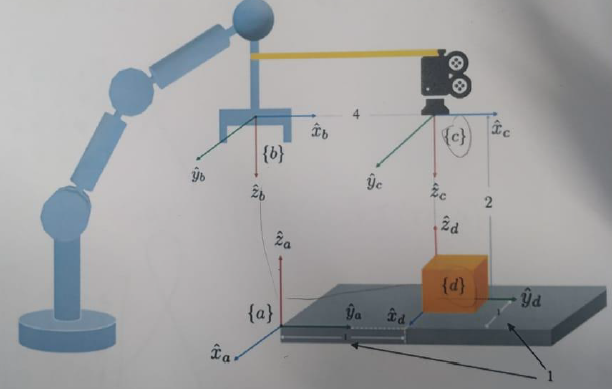

a) Tda

a1 = trans(1,0,0)

a1 =      1     0     0     1
     0     1     0     0
     0     0     1     0
     0     0     0     1


a2 = trans(0,-1,0)

a2 =      1     0     0     0
     0     1     0    -1
     0     0     1     0
     0     0     0     1


Tda = a1*a2

Tda =      1     0     0     1
     0     1     0    -1
     0     0     1     0
     0     0     0     1


b) Tdc

% rotação em z 90° --> rotação corrente em y 180° --> translação corrente em z de -2
b1 = trans(0,0,2)

b1 =      1     0     0     0
     0     1     0     0
     0     0     1     2
     0     0     0     1


b2 = rot('z',-90)

b2 =      0     1     0     0
    -1     0     0     0
     0     0     1     0
     0     0     0     1


b3 = rot('y',180)

b3 =     -1     0     0     0
     0     1     0     0
     0     0    -1     0
     0     0     0     1


b4 = trans(0,0,-2)

b4 =      1     0     0     0
     0     1     0     0
     0     0     1    -2
     0     0     0     1


Tdc = b1*b2*b3

Tdc =      0     1     0     0
     1     0     0     0
     0     0    -1     2
     0     0     0     1


Tdc = b2*b3*b4

Tdc =      0     1     0     0
     1     0     0     0
     0     0    -1     2
     0     0     0     1


c) Tcb

Tcb = trans(-4,0,0)

Tcb =      1     0     0    -4
     0     1     0     0
     0     0     1     0
     0     0     0     1


d) Tba

d1 = trans(3,1,2)

d1 =      1     0     0     3
     0     1     0     1
     0     0     1     2
     0     0     0     1


d2 = rot('z',90)

d2 =      0    -1     0     0
     1     0     0     0
     0     0     1     0
     0     0     0     1


d3 = rot('x',180)

d3 =      1     0     0     0
     0    -1     0     0
     0     0    -1     0
     0     0     0     1


d4 = trans(1,3,-2)

d4 =      1     0     0     1
     0     1     0     3
     0     0     1    -2
     0     0     0     1


Tba = d1*d2*d3

Tba =      0     1     0     3
     1     0     0     1
     0     0    -1     2
     0     0     0     1


Tba = d2*d3*d4

Tba =      0     1     0     3
     1     0     0     1
     0     0    -1     2
     0     0     0     1
